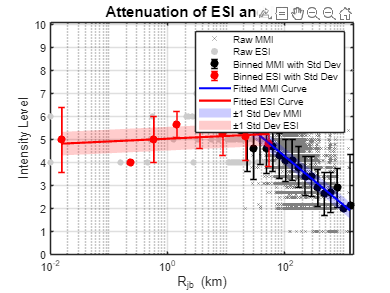

% Read MMI data from 'WP_DYFI.csv'
data_MMI = readtable('WP_DYFI.csv');

% Extract relevant columns for MMI
rjb_MMI = data_MMI.Rjb;
MMI = data_MMI.cdi;

% Read ESI and PGV data from 'GMIs_no_rp.xlsx'
data_ESI = readtable('GMIs_no_rp.xlsx');

% Extract relevant columns for ESI and PGV
rjb_ESI = table2array(data_ESI(2:end, 9));    % Epicentral Distance (rjb)
ESI = table2array(data_ESI(2:end, 5));        % Environmental Seismic Intensity (ESI)
PGV = table2array(data_ESI(2:end, 33));       % Peak Ground Velocity (PGV)
rjb_PGV = table2array(data_ESI(2:end, 34));   % Epicentral Distance for PGV (rjb2)

% Offset rjb values by 0.01 where rjb <= 0 to avoid log(0)
rjb_MMI(rjb_MMI <= 0) = 0.01;
rjb_ESI(rjb_ESI <= 0) = 0.01;
rjb_PGV(rjb_PGV <= 0) = 0.01;

% Filter and process MMI data
validIndices_MMI = ~isnan(rjb_MMI) & ~isnan(MMI) & (rjb_MMI > 0) & (MMI > 0);
rjb_filtered_MMI = rjb_MMI(validIndices_MMI);
MMI_filtered = MMI(validIndices_MMI);

% Define logarithmically spaced bins for MMI
numBins_MMI = 20;
logBinEdges_MMI = logspace(log10(min(rjb_filtered_MMI)), log10(max(rjb_filtered_MMI)), numBins_MMI + 1);

% Bin the MMI data and calculate bin centers
[~, ~, binIndices_MMI] = histcounts(rjb_filtered_MMI, logBinEdges_MMI);
binCenters_MMI = sqrt(logBinEdges_MMI(1:end-1) .* logBinEdges_MMI(2:end));

% Initialize arrays for binned MMI values and standard deviations
binnedMMI = nan(size(binCenters_MMI));
binnedMMI_std = nan(size(binCenters_MMI));

% Calculate median MMI and standard deviation for each bin
for i = 1:length(binCenters_MMI)
    inBin = (binIndices_MMI == i);
    if any(inBin)
        binnedMMI(i) = median(MMI_filtered(inBin));
        binnedMMI_std(i) = std(MMI_filtered(inBin));
    end
end

% Remove bins with NaN values
validBins_MMI = ~isnan(binnedMMI);
binCenters_MMI = binCenters_MMI(validBins_MMI);
binnedMMI = binnedMMI(validBins_MMI);
binnedMMI_std = binnedMMI_std(validBins_MMI);

% Filter and process ESI data, excluding ESI = 0
validIndices_ESI = ~isnan(rjb_ESI) & ~isnan(ESI) & (rjb_ESI > 0) & (ESI > 0);
rjb_filtered_ESI = rjb_ESI(validIndices_ESI);
ESI_filtered = ESI(validIndices_ESI);

% Define logarithmically spaced bins for ESI
numBins_ESI = 10;
logBinEdges_ESI = logspace(log10(min(rjb_filtered_ESI)), log10(max(rjb_filtered_ESI)), numBins_ESI + 1);

% Bin the ESI data and calculate bin centers
[~, ~, binIndices_ESI] = histcounts(rjb_filtered_ESI, logBinEdges_ESI);
binCenters_ESI = sqrt(logBinEdges_ESI(1:end-1) .* logBinEdges_ESI(2:end));

% Initialize arrays for binned ESI values and standard deviations
binnedESI = nan(size(binCenters_ESI));
binnedESI_std = nan(size(binCenters_ESI));

% Calculate mean ESI and standard deviation for each bin
for i = 1:length(binCenters_ESI)
    inBin = (binIndices_ESI == i);
    if any(inBin)
        binnedESI(i) = mean(ESI_filtered(inBin));
        binnedESI_std(i) = std(ESI_filtered(inBin));
    end
end

% Remove bins with NaN values for ESI
validBins_ESI = ~isnan(binnedESI);
binCenters_ESI = binCenters_ESI(validBins_ESI);
binnedESI = binnedESI(validBins_ESI);
binnedESI_std = binnedESI_std(validBins_ESI);


% Compute MMI from PGV using the provided piecewise equations
validIndices_PGV = ~isnan(rjb_PGV) & ~isnan(PGV);
rjb_filtered_PGV = rjb_PGV(validIndices_PGV);
PGV_filtered = PGV(validIndices_PGV);

log_PGV = log10(PGV_filtered);
MMI_PGV = zeros(size(PGV_filtered)); % Initialize MMI_PGV array

% Apply piecewise equations for MMI calculation
MMI_PGV(log_PGV <= 0.48) = 4.37 + 1.32 * log_PGV(log_PGV <= 0.48);
MMI_PGV(log_PGV > 0.48) = 3.54 + 3.03 * log_PGV(log_PGV > 0.48);

% Sort rjb_PGV and MMI_PGV for plotting
[rjb_PGV_sorted, sortIdx_PGV] = sort(rjb_filtered_PGV);
MMI_PGV_sorted = MMI_PGV(sortIdx_PGV);

% Define the attenuation model
attenuationModel = @(params, r) params(1) - params(2) * log10(r);
initialParams = [10, 1];
options = optimset('Display','off');

% Fit the attenuation model to the binned MMI data
fittedParams_MMI = lsqcurvefit(attenuationModel, initialParams, binCenters_MMI, binnedMMI, [], [], options);
MMI_fitted = attenuationModel(fittedParams_MMI, binCenters_MMI);

% Calculate residuals and standard deviation of the residuals for MMI
residuals_MMI = binnedMMI - MMI_fitted;
residualsStd_MMI = std(residuals_MMI);

% Calculate ±1 standard deviation bounds for the fitted MMI curve
MMI_fitted_upper = MMI_fitted + residualsStd_MMI;
MMI_fitted_lower = MMI_fitted - residualsStd_MMI;

% Fit the attenuation model to the binned ESI data (logarithmic bins)
fittedParams_ESI = lsqcurvefit(attenuationModel, initialParams, binCenters_ESI, binnedESI, [], [], options);
ESI_fitted = attenuationModel(fittedParams_ESI, binCenters_ESI);

% Calculate residuals and standard deviation of the residuals for ESI
residuals_ESI = binnedESI - ESI_fitted;
residualsStd_ESI = std(residuals_ESI);

% Calculate ±1 standard deviation bounds for the fitted ESI curve
ESI_fitted_upper = ESI_fitted + residualsStd_ESI;
ESI_fitted_lower = ESI_fitted - residualsStd_ESI;

% Binning ESI data in equally spaced 5 km bins
maxDistance = max(rjb_filtered_ESI);
binEdges_eq = 0:5:ceil(maxDistance/5)*5; % Ensures the last bin includes the max distance

% Bin the ESI data and calculate bin centers
[~, ~, binIndices_eq] = histcounts(rjb_filtered_ESI, binEdges_eq);
binCenters_eq = (binEdges_eq(1:end-1) + binEdges_eq(2:end)) / 2;

% Initialize array for binned ESI values and standard deviations
binnedESI_eq = nan(size(binCenters_eq));
binnedESI_std_eq = nan(size(binCenters_eq));

% Calculate the mean ESI and standard deviation for each bin
for i = 1:length(binCenters_eq)
    inBin = (binIndices_eq == i);
    if any(inBin)
        binnedESI_eq(i) = mean(ESI_filtered(inBin));
        binnedESI_std_eq(i) = std(ESI_filtered(inBin));
    end
end

% Remove bins with NaN values (i.e., bins without data)
validBins_eq = ~isnan(binnedESI_eq);
binCenters_eq = binCenters_eq(validBins_eq);
binnedESI_eq = binnedESI_eq(validBins_eq);
binnedESI_std_eq = binnedESI_std_eq(validBins_eq);

% Fit the attenuation model to the binned ESI data (equal bins)
fittedParams_ESI_eq = lsqcurvefit(attenuationModel, initialParams, binCenters_eq, binnedESI_eq, [], [], options);
ESI_fitted_eq = attenuationModel(fittedParams_ESI_eq, binCenters_eq);

% Calculate residuals and standard deviation
residuals_eq = binnedESI_eq - ESI_fitted_eq;
residualsStd_eq = std(residuals_eq);

% Calculate upper and lower bounds (+/- 1 standard deviation)
ESI_fitted_upper_eq = ESI_fitted_eq + residualsStd_eq;
ESI_fitted_lower_eq = ESI_fitted_eq - residualsStd_eq;

% Plotting combined data (First Figure)
figure;
hold on;
grid on;
box on;

% Plot raw MMI and ESI values as scatter plots
h_scatter_MMI = scatter(rjb_filtered_MMI, MMI_filtered, 20, 'x', 'MarkerEdgeColor', [0.5, 0.5, 0.5], 'DisplayName', 'Raw MMI');
h_scatter_ESI = scatter(rjb_filtered_ESI, ESI_filtered, 30, 'o', 'MarkerEdgeColor', [0.8, 0.8, 0.8], 'MarkerFaceColor', [0.8, 0.8, 0.8], 'DisplayName', 'Raw ESI');

% Plot binned MMI values with error bars
h_binned_MMI = errorbar(binCenters_MMI, binnedMMI, binnedMMI_std, 'ko', 'MarkerFaceColor', 'k', 'LineWidth', 1.5, 'DisplayName', 'Binned MMI with Std Dev');

% Plot binned ESI values with error bars
h_binned_ESI = errorbar(binCenters_ESI, binnedESI, binnedESI_std, 'ro', 'MarkerFaceColor', 'r', 'LineWidth', 1.5, 'DisplayName', 'Binned ESI with Std Dev');

% Ensure bin centers and fitted values are column vectors
binCenters_MMI = binCenters_MMI(:);
MMI_fitted = MMI_fitted(:);
MMI_fitted_upper = MMI_fitted_upper(:);
MMI_fitted_lower = MMI_fitted_lower(:);

binCenters_ESI = binCenters_ESI(:);
ESI_fitted = ESI_fitted(:);
ESI_fitted_upper = ESI_fitted_upper(:);
ESI_fitted_lower = ESI_fitted_lower(:);

% Create shaded region for ±1 standard deviation for MMI
x_shaded_MMI = [binCenters_MMI; flipud(binCenters_MMI)];
y_shaded_MMI = [MMI_fitted_upper; flipud(MMI_fitted_lower)];
h_fill_MMI = fill(x_shaded_MMI, y_shaded_MMI, 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
set(get(get(h_fill_MMI,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');

% Plot fitted MMI curve
h_plot_MMI = plot(binCenters_MMI, MMI_fitted, 'b-', 'LineWidth', 2, 'DisplayName', 'Fitted MMI Curve');

% Create shaded region for ±1 standard deviation for ESI
x_shaded_ESI = [binCenters_ESI; flipud(binCenters_ESI)];
y_shaded_ESI = [ESI_fitted_upper; flipud(ESI_fitted_lower)];
h_fill_ESI = fill(x_shaded_ESI, y_shaded_ESI, 'r', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
set(get(get(h_fill_ESI,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');

% Plot fitted ESI curve
h_plot_ESI = plot(binCenters_ESI, ESI_fitted, 'r-', 'LineWidth', 2, 'DisplayName', 'Fitted ESI Curve');

% Create dummy patches for the shaded regions in the legend
h_dummy_fill_MMI = patch(NaN, NaN, 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'DisplayName', '±1 Std Dev MMI');
h_dummy_fill_ESI = patch(NaN, NaN, 'r', 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'DisplayName', '±1 Std Dev ESI');

% Plot MMI_PGV as green solid line
%plot(rjb_PGV_sorted, MMI_PGV_sorted, 'g-', 'LineWidth', 1.5, 'DisplayName', 'MMI (from PGV)');

% Set axis labels, title, and legend
xlabel('R_{jb} (km)', 'FontSize', 12);
ylabel('Intensity Level', 'FontSize', 12);
title('Attenuation of ESI and MMI', 'FontSize', 14);

% Create custom legend with the desired order
legend([h_scatter_MMI, h_scatter_ESI, h_binned_MMI, h_binned_ESI, h_plot_MMI, h_plot_ESI, h_dummy_fill_MMI, h_dummy_fill_ESI],...
       {'Raw MMI', 'Raw ESI', 'Binned MMI with Std Dev', 'Binned ESI with Std Dev', 'Fitted MMI Curve', 'Fitted ESI Curve', '±1 Std Dev MMI', '±1 Std Dev ESI'},...
       'Location', 'northeast');

% Set logarithmic x-axis
set(gca, 'XScale', 'log');

% Set axes limits
xlim([min([logBinEdges_MMI, logBinEdges_ESI]), max([logBinEdges_MMI, logBinEdges_ESI])]);
ylim([min([ESI_filtered; MMI_filtered])-1, max([ESI_filtered; MMI_filtered]) + 1]);
yticks(0:1:10);

hold off;

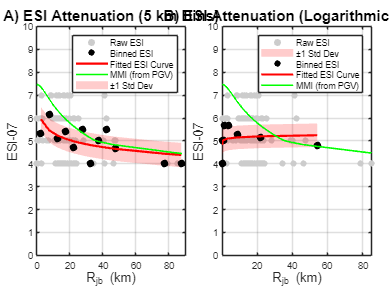


% Create a tiled layout with 1 row and 2 columns (Second Figure)
figure;
tiledlayout(1, 2, 'TileSpacing', 'Compact', 'Padding', 'Compact');

%% Plot A: Equally Spaced 5 km Bins
%% Plot A: Equally Spaced 5 km Bins
nexttile;
hold on;
grid on;
box on;

% Plot raw ESI values as light gray scatter plot
h_raw_ESI = scatter(rjb_filtered_ESI, ESI_filtered, 30, 'MarkerEdgeColor', [0.8, 0.8, 0.8], ...
    'MarkerFaceColor', [0.8, 0.8, 0.8], 'DisplayName', 'Raw ESI');

% Ensure binCenters_eq, ESI_fitted_upper_eq, and ESI_fitted_lower_eq are column vectors
binCenters_eq = binCenters_eq(:);
ESI_fitted_upper_eq = ESI_fitted_upper_eq(:);
ESI_fitted_lower_eq = ESI_fitted_lower_eq(:);

% Plot shaded area for ±1 standard deviation
X_fill_eq = [binCenters_eq; flipud(binCenters_eq)];
Y_fill_eq = [ESI_fitted_upper_eq; flipud(ESI_fitted_lower_eq)];
h_fill_eq = fill(X_fill_eq, Y_fill_eq, 'r', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
% Exclude the fill from the legend
set(get(get(h_fill_eq,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');

% Plot binned ESI values as black circles
h_binned_ESI = scatter(binCenters_eq, binnedESI_eq, 50, 'ko', 'filled', 'DisplayName', 'Binned ESI');

% Plot fitted attenuation curve as red solid line
h_fitted_ESI = plot(binCenters_eq, ESI_fitted_eq, 'r-', 'LineWidth', 2, 'DisplayName', 'Fitted ESI Curve');

% Plot MMI_PGV as green solid line
h_MMI_PGV = plot(rjb_PGV_sorted, MMI_PGV_sorted, 'g-', 'LineWidth', 1.5, 'DisplayName', 'MMI (from PGV)');

% Create a dummy patch for the shaded region in the legend
h_dummy_fill_eq = patch(NaN, NaN, 'r', 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'DisplayName', '±1 Std Dev');

% Set axis labels and title
xlabel('R_{jb} (km)', 'FontSize', 12);
ylabel('ESI-07', 'FontSize', 12);
title('A) ESI Attenuation (5 km Bins)', 'FontSize', 14);

% Create custom legend with the desired order
legend([h_raw_ESI, h_binned_ESI, h_fitted_ESI, h_MMI_PGV, h_dummy_fill_eq], ...
    {'Raw ESI', 'Binned ESI', 'Fitted ESI Curve', 'MMI (from PGV)', '±1 Std Dev'}, 'Location', 'northeast');

% Set axes limits
xlim([0, max(binEdges_eq)]);
ylim([0, 10]);

hold off;


%% Plot B: Logarithmic Bins
nexttile;
hold on;
grid on;
box on;

% Plot raw ESI values as light gray scatter plot
scatter(rjb_filtered_ESI, ESI_filtered, 30, 'MarkerEdgeColor', [0.8, 0.8, 0.8], ...
    'MarkerFaceColor', [0.8, 0.8, 0.8], 'DisplayName', 'Raw ESI');

% Plot shaded area for ±1 standard deviation
X_fill_log = [binCenters_ESI; flipud(binCenters_ESI)];
Y_fill_log = [ESI_fitted_upper; flipud(ESI_fitted_lower)];
fill(X_fill_log, Y_fill_log, 'r', 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'DisplayName', '±1 Std Dev');

% Plot binned ESI values as black circles
scatter(binCenters_ESI, binnedESI, 50, 'ko', 'filled', 'DisplayName', 'Binned ESI');

% Plot fitted attenuation curve as red solid line
plot(binCenters_ESI, ESI_fitted, 'r-', 'LineWidth', 2, 'DisplayName', 'Fitted ESI Curve');

% Plot MMI_PGV as green solid line
plot(rjb_PGV_sorted, MMI_PGV_sorted, 'g-', 'LineWidth', 1.5, 'DisplayName', 'MMI (from PGV)');

% Set axis labels and title
xlabel('R_{jb} (km)', 'FontSize', 12);
ylabel('ESI-07', 'FontSize', 12);
title('B) ESI Attenuation (Logarithmic Bins)', 'FontSize', 14);

% Set legend
legend('Location', 'northeast');

% Set axes limits
xlim([min(logBinEdges_ESI), max(logBinEdges_ESI)]);
ylim([0, 10]);

% Set x-axis to logarithmic scale
%set(gca, 'XScale', 'log');

hold off;